# Zadanie 3 - Analityczne rozwiązanie

# równania Poissona dla złącza p-n

### Aleksander Cząstkiewicz - 260763

Nc=6.2e15*300^(3/2);
Nv = 3.5e15*300^(3/2);
Eg=1.12;%%[eV]
Nd=6.3e15; %%[cm^-3]
Na=3.6e15; %%[cm^-3]
k=1.381e-23;%[J/K]
q=1.602e-19;%%[C]
epsilon_0=8.854187817e-12;%%[F/m]
epsilon_r=11.68;
epsilon=epsilon_r*epsilon_0;%%[F/m]
n_i=sqrt(Nc*Nv)*exp(-Eg/(2*k*300/1.6e-19));%%[cm^-3]
Ei=Eg/2;
Ef_n=-log(Nd/n_i)*k/1.6e-19*300+Ei;%%[eV]
Ef_p=-log(Na/n_i)*k/1.6e-19*300+Ei;%%[eV]
V_bi=log(Nd*Na/n_i/n_i)*k*300/q;%%[V]
W=sqrt(2*epsilon/q*V_bi*(1/Na+1/Nd))/10.0;%%[sqrt(F/m/C*V*(cm^3))=sqrt(A^2*s^4*V*cm^3/(kg*m^3*C))=sqrt(cm^3/m)=sqrt(cm^2*0.01m/m)=cm*0.1]*10-> [cm]
x_p=W*Nd/(Nd+Na);%%[cm]
x_n=W*Na/(Nd+Na);%%[cm]

    W tym zadaniu wykorzystano analityczne roziwązanie równiania Poissona dla złączna p-n w przybliżeniu obszaru całkowicie zubożonego. Przyjęto koncentracje domieszek: $N_d =6\ldotp 3\textrm{e15}\left\lbrack {\textrm{cm}}^{-3} \right\rbrack \;$w półprzewodniku typu n i $N_a =3\ldotp 6\textrm{e15}\left\lbrack {\textrm{cm}}^{-3} \right\rbrack \;$w półprzewodniku typu p. Pierw wyliczono ładunek przestrzenny $\rho \left\lbrack {C\cdot \textrm{cm}}^{-3} \right\rbrack$ . Na jego podstawie ustalono pole elektryczne $E\left\lbrack \frac{V}{\textrm{cm}}\right\rbrack$ i potencjał pola $V\left\lbrack V\right\rbrack$, które zadanao analitycznie z kolejnych całkowań $\rho$(pole el. z pierwszego całkowania, natomiast potencjał z drugiego). Następnie przedstawiono te wartości na wykresie w funkcji głębokości złącza. Na końcu policzono energie fermiego dla poszeczegółnych częsći łącza i korzystając ze znanej wartości przerwy energetycznej${\;}^{\left\lbrack 1\right\rbrack }$ przedstawiono na wykresie digram pasmowy.

X=-3.0*x_p:(x_n+x_p)/300.0:3.0*x_n;%%[cm]
N=zeros(size(X)); %%[cm^-3]
rho=zeros(size(X));%%[C*cm^-3]
E_el=zeros(size(X));
V=zeros(size(X)); %%[V]
for i=1:size(X,2)
    if(X(1,i)>0)
        if(X(1,i)<x_n)
        N(1,i)=Nd(1);
        end
        rho(1,i)=q*N(1,i);%%[C*cm^-3]
        E_el(1,i)=-q*N(1,i)/epsilon*(x_n-X(1,i))*100.0;%%100*[V/cm]->[V/cm]
        if(X(1,i)>=x_n)
        V(1,i)=(-q*Nd/epsilon*(x_n-x_n/2.0)*x_n-q*Na/2.0/epsilon*x_p*x_p)*100.0; %%100[V]->[V]
        else
        V(1,i)=(-q*N(1,i)/epsilon*(x_n-X(1,i)/2.0)*X(1,i)-q*Na/2.0/epsilon*x_p*x_p)*100.0; %%100[V]->[V]    
        end
        N(1,i)=Nd(1);
    else 
        if(X(1,i)>-x_p)
        N(1,i)=Na(1);
        end
        rho(1,i)=-q*N(1,i);%%[C*cm^-3]
        E_el(1,i)=-q*N(1,i)/epsilon*(x_p+X(1,i))*100.0;%100*[V/cm]->[V/cm]
        if(X(1,i)<=-x_p)
        V(1,i)=(-q*Na/epsilon*(x_p+(-x_p)/2.0)*(-x_p)-q*Na/2.0/epsilon*x_p*x_p)*100.0; %%100[V]->[V]
        else
        V(1,i)=(-q*N(1,i)/epsilon*(x_p+X(1,i)/2.0)*X(1,i)-q*Na/2.0/epsilon*x_p*x_p)*100.0; %%100[V]->[V]    
        end
        N(1,i)=Na(1);
    end
end 

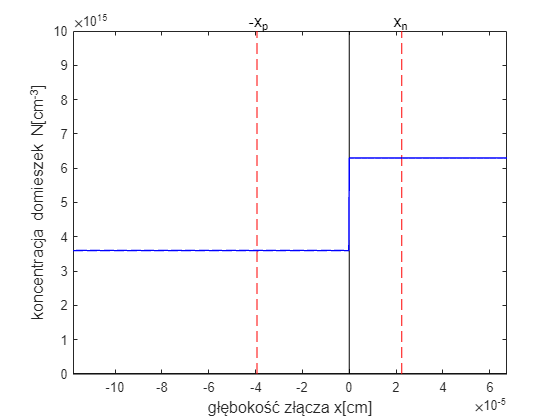



plot([min(X) max(X)], [0 0], 'Color', 'k');
hold on
xlim([-3.0*x_p,x_n*3.0]);
ylim([0e15,10e15]);
plot([0 0], [0e15,10e15], 'Color', 'k');
plot([-x_p -x_p], [0e15,10e15], 'Color', 'red','LineStyle','--');
plot([x_n x_n], [0e15,10e15], 'Color', 'red','LineStyle','--');
xlabel("głębokość złącza x[cm]","FontSize",12);
ylabel("koncentracja domieszek N[cm^{-3}]","FontSize",12);
text(-x_p-0.42e-5,10.2e15,"-x_p","FontSize",12);
text(x_n-0.42e-5,10.2e15,"x_n","FontSize",12);
plot(X,N,'color','blue','LineWidth',1.1)
hold off

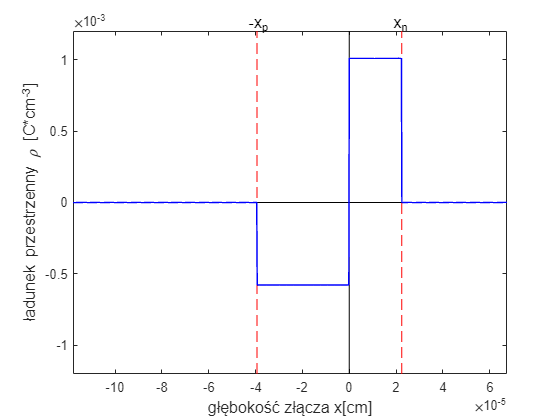



plot([min(X) max(X)], [0 0], 'Color', 'k');
hold on
xlim([-3.0*x_p,x_n*3.0]);
ylim([-12e-4,12e-4]);
plot([0 0], [-12e-4,12e-4], 'Color', 'k');
plot([-x_p -x_p], [-12e-4,12e-4], 'Color', 'red','LineStyle','--');
plot([x_n x_n], [-12e-4,12e-4], 'Color', 'red','LineStyle','--');
xlabel("głębokość złącza x[cm]","FontSize",12);
ylabel("ładunek przestrzenny \rho [C*cm^{-3}]","FontSize",12);
text(-x_p-0.42e-5,12.4e-4,"-x_p","FontSize",12);
text(x_n-0.42e-5,12.4e-4,"x_n","FontSize",12);
plot(X,rho,'color','blue','Linewidth',1.1)
hold off

Prho_p=-x_p*(q*Na);
Prho_n=x_n*(-q*Nd);
fprintf("Pole pod wykresem dla strony typu n wynosi "+num2str(Prho_n)+"[C*cm^{-2}], a dla typu p "+num2str(Prho_n)+"[C*cm^{-2}].");

Pole pod wykresem dla strony typu n wynosi2.2673e-08[C*cm^{-2}], a dla typu p 2.2673e-08[C*cm^{-2}].

 %%komentarz

Widać że pola te są takiej samej wartości co jest zgodne z teoretycznymi założeniami, mianowicie z warunkiem neutralności qAx_pNa=qAx_nNd. Przekrój powierzchni jest ten sam, więc widać , że warnek ten jest spełniony.

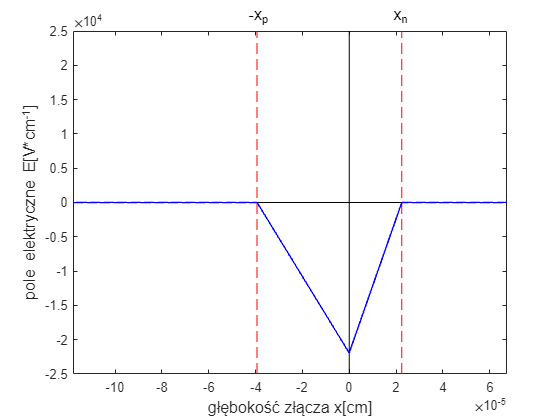

plot([min(X) max(X)], [0 0], 'Color', 'k');
hold on
xlim([-3.0*x_p,x_n*3.0]);
ylim([-2.5e4,2.5e4]);
plot([0 0], [-2.5e4,2.5e4], 'Color', 'k');
plot([-x_p -x_p], [-2.5e4,2.5e4], 'Color', 'red','LineStyle','--');
plot([x_n x_n], [-2.5e4,2.5e4], 'Color', 'red','LineStyle','--');
xlabel("głębokość złącza x[cm]","FontSize",12);
ylabel("pole elektryczne E[V*cm^{-1}]","FontSize",12);
text(-x_p-0.42e-5,2.7e4,"-x_p","FontSize",12);
text(x_n-0.42e-5,2.7e4,"x_n","FontSize",12);
plot(X,E_el,'color','blue','Linewidth',1.1)
hold off

Zgodnie z założeniami przybliżenia, pole elektryczne występuje tylko w obszarze zubożonym.

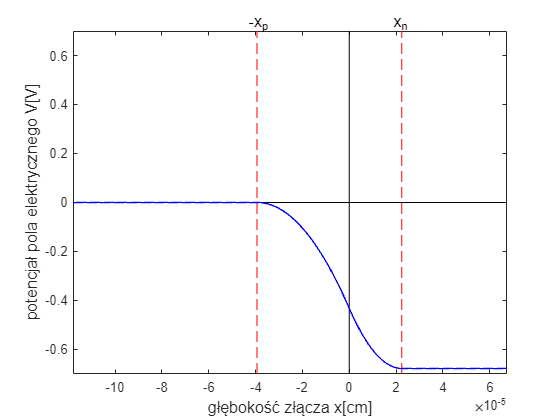

plot([min(X) max(X)], [0 0], 'Color', 'k');
hold on
xlim([-3.0*x_p,x_n*3.0]);
ylim([-0.7,0.7]);
plot([0 0], [-0.7,0.7], 'Color', 'k');
plot([-x_p -x_p], [-0.7,0.7], 'Color', 'red','LineStyle','--');
plot([x_n x_n], [-0.7,0.7], 'Color', 'red','LineStyle','--');
xlabel("głębokość złącza x[cm]","FontSize",12);
ylabel("potencjał pola elektrycznego V[V]","FontSize",12);
text(-x_p-0.42e-5,0.73,"-x_p","FontSize",12);
text(x_n-0.42e-5,0.73,"x_n","FontSize",12);
plot(X,V,'color','blue','Linewidth',1.1)
hold off

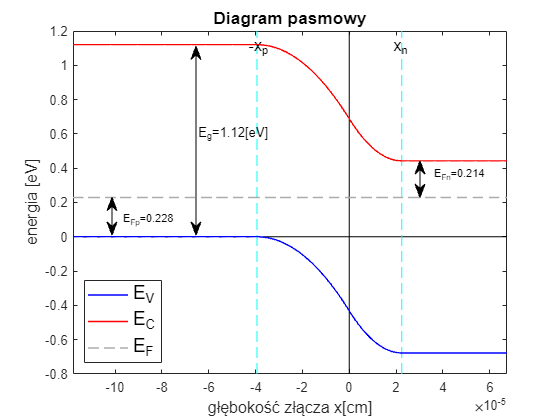

%%xlim([-x_p,x_n]);
EV=V*(q)/q;%%[J]->eV
EC=EV+Eg; %%[eV+eV]
Ef1=min(EC)-Ef_n;
Ef2=max(EV)+Ef_p;
Ef=(Ef1+Ef2)/2.0;
EF=zeros(size(X))+Ef;
plot([min(X) max(X)], [0 0], 'Color', 'k');
hold on
xlim([-3.0*x_p,x_n*3.0]);
ylim([-0.8,1.2]);
plot([0 0], [-0.8,1.2], 'Color', 'k');
plot([-x_p -x_p], [-0.8,1.2], 'Color', 'cyan','LineStyle','--');
plot([x_n x_n], [-0.8,1.2], 'Color', 'cyan','LineStyle','--');
xlabel("głębokość złącza x[cm]","FontSize",12);
ylabel("energia [eV]","FontSize",12);
text(-x_p-0.42e-5,1.1,"-x_p","FontSize",12);
text(x_n-0.42e-5,1.1,"x_n","FontSize",12);

plot(X,EV,'color','blue','Linewidth',1.1)
plot(X,EC,'color','red','Linewidth',1.1)
plot(X,EF,'color',[172/255 172/255 172/255],'Linewidth',1.1,'LineStyle','--')
hold off
legend("","","","","E_V","E_C","E_F","Location","southwest","FontSize",14);
title("Diagram pasmowy","FontSize",13);
annotation('arrow',[0.35,0.350],[0.44,0.89],'Color','k','LineWidth',0.75);
annotation('arrow',[0.350,0.350],[0.89,0.44],'Color','k','LineWidth',0.75);
text(-6.5e-5,0.6,"E_g=1.12[eV]","FontSize",10);
annotation('arrow',[0.2,0.20],[0.44,0.53],'Color','k','LineWidth',0.45);
annotation('arrow',[0.2,0.20],[0.53,0.44],'Color','k','LineWidth',0.45);
text(-9.7e-5,0.1,"E_{Fp}="+num2str(Ef_p(1),3),"FontSize",8);
annotation('arrow',[0.75,0.750],[0.53,0.617],'Color','k','LineWidth',0.45);
annotation('arrow',[0.75,0.750],[0.617,0.53],'Color','k','LineWidth',0.45);
text(3.6e-5,0.36,"E_{Fn}="+num2str(Ef_n(1),3),"FontSize",8);

## Źródła:

[1] Instytut Fizyko Techniczny imienia A. F. Ioffego Rosyjskiej Akademii Nauk w Petersburgu

http://www.ioffe.ru/SVA/NSM/Semicond/Si